Resize and pad all photos to 512 x 512

data = batchcropIm('data');

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 3 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 24).
PASSED:/home/echo/bolete/data_pipeline/data/alessioporus-rubriflavus/Alessioporus-rubriflavus-stretched-netting-Jason-Bolin.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriflammeus/aureoboletus-auriflammeus-2.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriflammeus/aureoboletus-auriflammeus-7.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-1.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-14.jpg
PASSED:/home/echo/bolete/data_pipeline/data/aureoboletus-auriporus/aureoboletus-auriporus-4.jpg
PASSED:/home/echo/bolete/data_pipeline/data/au

Gather corresponding labels for each image

names = data.fileName;
newNames = string.empty(length(names),0);
for i=1:length(names)
    sp = split(names{i},'/');
    names(i) = sp(7);
end
data.name = names;
labels = readtable('clean_data/labels.csv');
data = join(data, labels, "LeftKeys","name","RightKeys","NewName");

Cut off species with 5 or fewer pictures

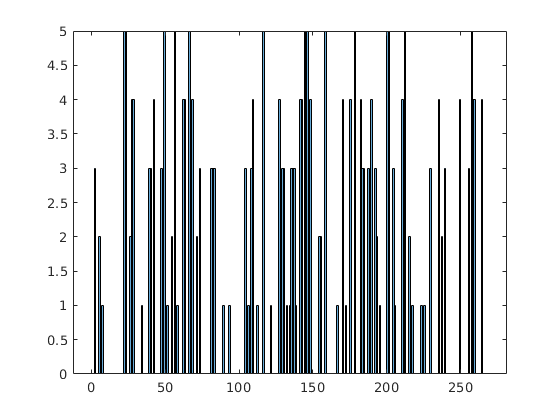

u = unique(data.ID);
[vals, ~] = histcounts(data.ID, [u;length(u)+1]);
keep = ismember(data.ID, u(vals >= 6));
histogram(data.ID(~keep), [u;length(u)+1])

data = data(keep,:);

ids_remaining =      1
     3
     4
     6
     8
     9
    10
    11
    12
    13


newIds =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49



newIdCol =

  1947×0 empty uint64 matrix



oldvars = 1×49 cell array
    {'im'}    {'fileName'}    {'name'}    {'ID'}    {'Name'}    {'Images'}    {'F1'}    {'F2'}    {'F3'}    {'F4'}    {'F5'}    {'F6'}    {'F7'}    {'F8'}    {'F9'}    {'F10'}    {'F11'}    {'F12'}    {'F13'}    {'F14'}    {'F15'}    {'F16'}    {'F17'}    {'F18'}    {'F19'}    {'F20'}    {'F21'}    {'F22'}    {'F23'}    {'F24'}    {'F25'}    {'F26'}    {'F27'}    {'F28'}    {'F29'}    {'F30'}    {'F31'}    {'F32'}    {'F33'}    {'F34'}    {'F35'}    {'F36'}    {'F37'}    {'F38'}    {'F39'}    {'F40'}    {'F41'}    {'F42'}    {'F43'}


data = 1947×50 table
    newID           im                                                                       fileName                                                                            name                 ID              Name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                   

Move images to matrix

N = height(data);
imageSize = size(data.im{1});
d = zeros(N,imageSize(1), imageSize(2), imageSize(3), "uint8");
ims = data.im;
parfor i = 1:N
    d(i,:,:,:) = ims{i};
end

Compare images and remove similar images

s = compareImages(d, 1e-9);
keep = sum(s) == 1;
d = d(keep,:,:,:);
data = data(keep,:);

Cut off species with 5 or fewer pictures

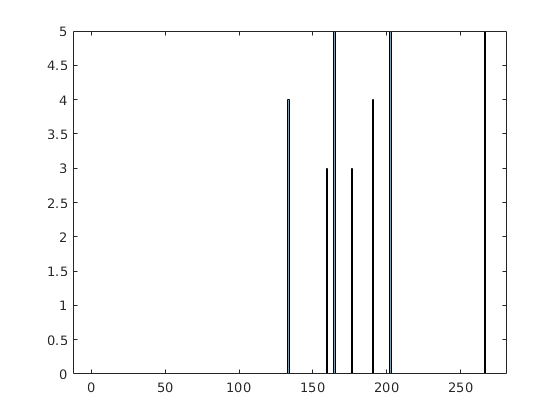

u = unique(labels.ID);
[vals, edges] = histcounts(data.ID, [u;length(u)+1]);
keep = ismember(data.ID, u(vals >= 6));
histogram(data.ID(~keep), [u;length(u)+1])

data = data(keep,:);
d = d(keep,:,:,:);

Re-map ID's so they are 0 indexed and in order

N = height(data);
ids_remaining = sort(unique(data.ID));
newIds = 0:length(ids_remaining)-1;

newIdCol = uint64.empty(N,0);
for img = 1:N
    newIdCol(img) = newIds(ids_remaining==data.ID(img));
end
oldvars = data.Properties.VariableNames;
data.newID = newIdCol';
data = data(:, ["newID", oldvars]);

data = 1947×53 table
    newID    newID_3    newID_2    newID_1           im                                                                       fileName                                                                            name                 ID              Name                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                               

Save new ID's for reference

nameIdTable = table();
nameIdTable.OldID = ids_remaining;
nameIdTable.NewID = newIds';
nameIdTable = join(nameIdTable, labels, "LeftKeys","OldID", "RightKeys", "ID", "RightVariables", "NewName");

nameIdTable = 179×3 table
    OldID    NewID               NewName            
    _____    _____    ______________________________

      1        0      {'alessioporus-rubriflavus'  }
      3        1      {'aureoboletus-auriflammeus' }
      4        2      {'aureoboletus-auriporus'    }
      6        3      {'aureoboletus-flaviporus'   }
      8        4      {'aureoboletus-innixus'      }
      9        5      {'aureoboletus-mirabilis'    }
     10        6      {'aureoboletus-projectellus' }
     11        7      {'aureoboletus-roxanae'      }
     12        8      {'aureoboletus-russellii'    }
     13        9      {'austroboletus-gracilis'    }
     14       10      {'austroboletus-subflavidus' }
     15       11      {'baorangia-bicolor'         }
     16       12      {'baorangia-rufomaculata'    }
     17       13      {'boletellus-ananas'         }
     18       14      {

writetable(nameIdTable, 'clean_data/final_ids.csv');

Permute the rows of the data so it's randomized

idx = randperm(size(d,1));
assert(size(d,1) == size(data,1));
d = d(idx,:,:,:);
data = data(idx,:);

Remove Existing H5 file

% !rm bolete.h5
!rm bolete_lowres.h5
fname = "bolete_lowres.h5"

Create H5 dataset

N = height(data);
imageSize = size(data.im{1});
sz = [Inf, imageSize];
h5create(fname, '/bolete-images', sz, "Datatype","uint8","ChunkSize", [1 imageSize])

Write images to dataset file

h5write(fname,'/bolete-images', d, [1, 1, 1, 1], [N, imageSize])

Write labels to dataset file

ids = uint64(data.newID);
h5create(fname, '/bolete-labels', Inf, "Datatype","uint64","ChunkSize", 1)
h5write(fname, '/bolete-labels', ids, 1, N)

Write features to file

vars = data.Properties.VariableNames;
characteristics = data{:, vars(find(vars == "F1"):end-5)};
chars = uint8(characteristics);
imageSize = size(chars, 2);
h5create(fname, '/bolete-characteristics', [Inf imageSize], "Datatype","uint8","ChunkSize", [1, imageSize]);
h5write(fname, '/bolete-characteristics', chars, [1 1], [N, imageSize]);

Write edibility to file

eds = data{:, vars(end-4:end)};
eds = uint8(eds);
imageSize = size(eds, 2);
h5create(fname, '/bolete-edibility', [Inf imageSize], "Datatype","uint8","ChunkSize", [1, imageSize]);
h5write(fname, '/bolete-edibility', eds, [1 1], [N, imageSize]);